# Laboratório de Controle - Aula 2 - 2022/1

## Introdução ao Matlab

## **Nome**: 

turma=0;
I=0;
datetime('now')
pwd

**Link para documento sobre o **[**Matlab**](https://drive.google.com/file/d/10LGfFSPo5F7xOj7fNbWo8_Iu55dQot34/view?usp=sharing)

**Importante: nos comandos abaixo, não use ponto e vírgula após  comandos que geram resultados que devem aparecer no relatório!**

**Afinal, é o resultado que mostra se o comando está correto!**

**Atividade 1: Comandos para manipular variáveis**

*1.1 Criar um número complexo *$z=x+jy$, *com *$x\neq0$, $y\neq0$ *e calcular seu valor absoluto.*

*1.2 Definir uma matriz A qualquer com dimensão 4x4 e com determinante diferente de zero (Dois comandos, e mostrar a matriz e seu determinante ).*

*1.3 Definir um vetor b não nulo com dimensão 4x1 e então obter x que satisfaz A*x=b (dois comandos)*

1.4 Salvar apenas as variáveis A,x,b em um arquivo  (seu nome).mat

1.5 Calcular o polinômio característico de A e depois suas raízes (dois comandos e mostrar)

1.6 Gerar um vetor z com 100 elementos uniformemente espaçados  de -2 a 2. Usar ; após o comando, e mostrar z com o comando plot(z).

1.7 Criar uma variável M do tipo struct com os campos (fields) nome, turma, I, data (dia:mês:ano) e atribuir valores aos mesmos

1.8 Criar um vetor y com 150 elementos vindos de uma distribuicão normal. Usar ; após o comando. Plotar então o histograma de y para confirmar sua distribuição normal. 

*1.9 Usar um comando apenas para contar quantos valores de y são maiores que zero.*

*1.10 Com no máximo dois comandos, substituir todos elementos negativos de y por zero, gerando y1. Plote plot([y y1]) para confirmar o sucesso dos comandos.*

**Atividade 2: Comandos para plotar dados e respostas de sistemas**

**Importante: Ao usar comandos para gerar figuras no relatório, comece com o comando figure, que abre uma nova figura, garantindo assim que nada será plotado sobre figuras já existentes.**

Sejam as variáveis x,y1,y2,y3.

x=linspace(0,6*pi,200); y1=sin(x); y2=sin(5*x); y3=y1+y2;

2.1 Dê os comandos para plotar y1,y2,y1+y2 exatamente como na figura mostrada. Ou seja, gere uma figura igual! 

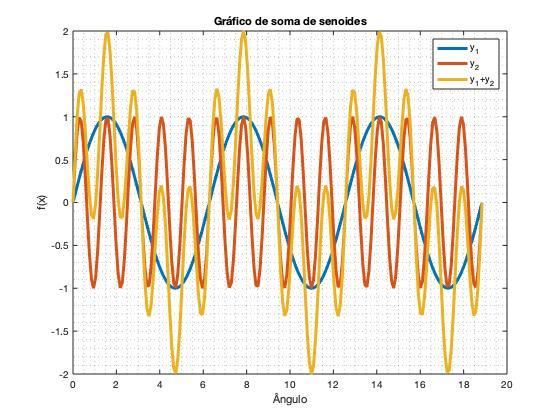

figure


2.2 Dê  os comandos  para produzir uma figura como a mostrada abaixo (Dica: subplot)

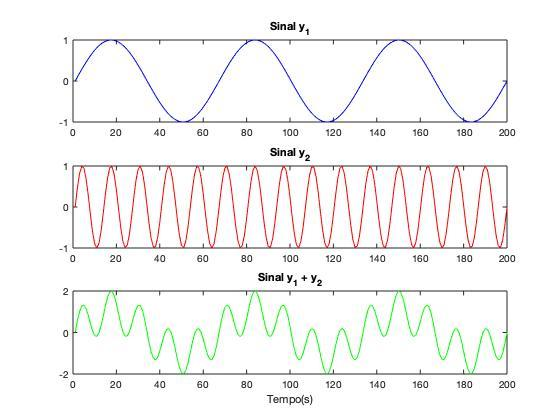

figure


2.3 Dê os comandos para gerar o gráfico de dispersão de y1 versus y2 conforme a figura mostrada (dica: scatter)

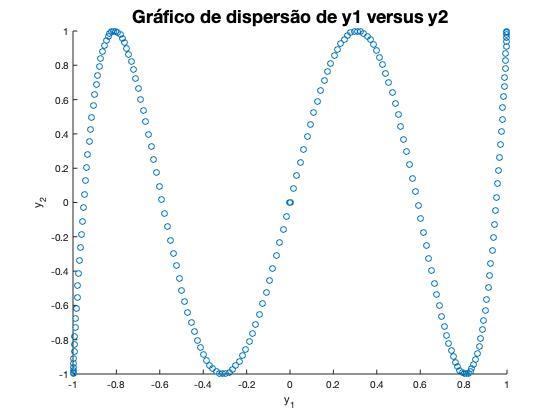

figure


2.4 Crie uma nova figura e plote y1 e plote em todos os picos deste sinal  o caractere 'X', em vermelho. As coordenadas dos picos devem ser obtidas na janela Command Window do Matlab antes de executar este código. Dica: ver ginput.

figure


2.5 Plote a figura abaixo (beijaflor.png) (Dica: imshow)

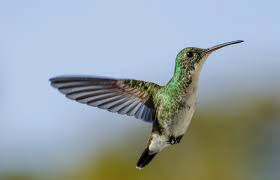

figure


2.6 Execute os comandos abaixo e descreva o que cada um deles faz

figure;
C=diag([1:10],0);
imagesc(C);
colorbar;

Resposta:

2.7 Analisar o heatmap gerado pelo código abaixo, e comentar o que é mostrado.

Resposta:

tbl = readtable(fullfile(matlabroot,'examples','graphics','TemperatureData.csv'));
head(tbl,5)
h = heatmap(tbl,'Month','Year','ColorVariable','TemperatureF');

Resposta:

2.8 *Criar um vetor w com 1000 valores aleatórios vindos de uma distribuição normal e plotar seu histograma com o comando histogram. Observe o histograma e obtenha aproximadamente sua média*

Resposta:

*2.9 Criar um vetor y com 10 valores aleatórios vindos de uma distribuição normal (randn) e plotar seus valores com o comando bar e depois com o comando stem*

2.10  Dê os comandos abaixo e verifique se o gráfico de barras gerado permite diferenciar as espécies de flor setosa a versicolor. Ver [Fisheriris](https://www.mathworks.com/help/stats/classification-example.html)

load fisheriris
bar(meas(46:55,:));xlabel('Conjuntos');ylabel('Características');

Resposta:

**Atividade 3: Comandos para definir e manipular modelos **

3.1 Defina a função de transferência $G=\frac{10}{s^2+(I/12)*s+10}$ e obtenha sua sobreelevação e tempo de estabelecimento ( Dica: stepinfo).

3.2 Obtenha os polos e zeros de G.

3.3 Mostre a resposta de G a um degrau de amplitude I.

3.4 Obtenha a função de transferência de malha fechada de G

3.5 Crie uma tabela onde cada linha corresponde a um ganho K e nas colunas sejam mostrada a sobreelevação, o tempo  de subida e tempo de estabelecimento (ver itens 2.8 e 2.9 de  [Matlab](https://drive.google.com/file/d/10LGfFSPo5F7xOj7fNbWo8_Iu55dQot34/view)) para o sistema de malha fechada com estes ganhos, $M(s)=\frac{KG(s)}{1+KG(s)}$, para G(s) do item 3.1. Dica: table e stepinfo.

Troque a figura ao lado por outra de sua preferência.